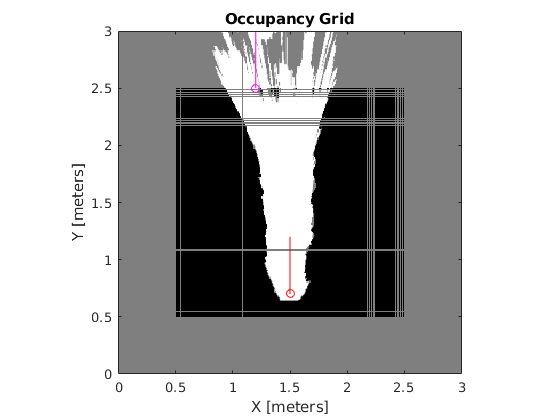

occGrid=occgrid;
show(occGrid)

% Set the start and goal poses
start = [1.5, 0.7, pi/2];
goal = [1.2, 2.5, pi/2];

% Show the start and goal positions of the robot
hold on
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')

% Show the start and goal headings
r = 0.5;
plot([start(1), start(1) + r*cos(start(3))], [start(2), start(2) + r*sin(start(3))], 'r-' )
plot([goal(1), goal(1) + r*cos(goal(3))], [goal(2), goal(2) + r*sin(goal(3))], 'm-' )
hold off

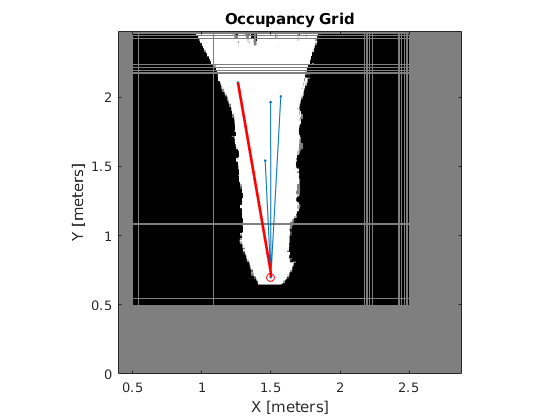


bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;
planner = plannerRRT(ss, stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

rng(0,'twister')
[pthObj, solnInfo] = plan(planner, start, goal);

show(occGrid)
hold on

% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');

% Interpolate and plot path
interpolate(pthObj,300)
plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)

% Show the start and goal in the grid map
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

function isReached = exampleHelperCheckIfGoal(planner, goalState, newState)
    isReached = false;
    threshold = 0.1;
    if planner.StateSpace.distance(newState, goalState) < threshold
        isReached = true;
    end
end